# **PROJET D'OPTIMISATION GLOBALE **

**Objectif :** Minimiser le coût de revient du réseau sur une journée d’été.

La variable d'optimisation X est un vecteur ligne 1x48. Les 24 premières colonnes correspondent aux puissances fournies à l'électrolyseur à chaque heure sur les 24h de la journée. Les 24 colonnes suivantes correspondent aux valeurs teta_elec associée à chaque heure de la journée. teta_elec vaut 1 (on) si on active l'électrolyseur et 0 (off) si on ne l'allume pas. 

clear 

data = load ("EteV35Nu10.txt") ;

N = 24 ; %N = nombre d'heures étudiées (On a 2N variables dans notre vecteur d'étude)

%Données à chaque heure 
H = data(:,1) ; %les 24 heures de la journée 
D = data(:,2)'; %vecteur Nx1 des demandes en électricité par heure sur 24h en MW
Peol = data(:,3)'; %vecteur de la puissance éolienne produite par heure en MW 
Ppv = data(:,4)'; %vecteur de la puissance solaire produite par heure en MW
Cext = data(:,end)' ; %Coût de l'électricité du réseau par heure en €/MW
Celec = ones(1,N) ; %Coût de fonctionnement de l'électrolyseur en €/MW

%Autres données
etat_elec = 0.6 ; %Rendement de l'électrolyseur 
Pmax_elec = 30 ;%Pmax de l'électrolyseur par heure en MW 
Pmin_elec = 5 ; %Pmin de l'électrolyseur par heure  en MW

%Quantités minimales d'hydrogène à produire par jour en MW (choisie arbitrairement)
Qjour_H2_ga = linspace(50,200,4); %pour le solver ga
Qjour_H2_pso = [100]; %pour le solver pso 


### **1.Définition de la fonction objectif à minimiser**

La fonction objectif à minimiser est la fonction des coûts de la production électrique sur une journée d'été en fonction des puissances fournies à l'électrolyseur et des variables "on-off" (définissent si l'électrolyseur fonctionne ou pas) à chaque heure. 

Pext = D + Pelec - Peol - Ppv 

Si Pext > 0 --> on achète de l'électricité au réséau

Si Pext < 0 --> on vend de l'électricité au réséau

Si Pext = 0 --> on ne fait rien 

%fonction objectif (prend un vecteur ligne en entrée pour être compatible
%avec le solver ga) 

%Le premier terme de la somme correspond au coût (positif ou négatif) lié à
%l'achat ou la vente d'ékectricité sur le réseau. Le deuxième terme
%correspond au coût de fonctionnement de l'électrolyseur. 

fobj = @(X) (D +X(1,1:N).*X(1,N+1:2*N) - Peol - Ppv)*Cext' + X(1,1:N).*X(1,N+1:2*N)*Celec' ; 


### **2.Définition des contraintes**

%Contraintes inégalités linéaires 

%Contrainte Σ𝜂𝑒𝑙𝑒𝑐𝑃𝑒𝑙𝑒𝑐 ≥ 𝑄𝐻2𝑗𝑜𝑢r soit -Σ𝜂𝑒𝑙𝑒𝑐𝑃𝑒𝑙𝑒𝑐 <= -𝑄𝐻2𝑗𝑜𝑢r
Aineq_lin1 = [-etat_elec*ones(1,N),zeros(1,N)] ;
% bineq_lin1 : défini dans la boucle for en partie 4 

%Contraintes Pelec > teta_elec*Pmin soit -Pelec + teta_elec*Pmin < 0
Aineq_lin2 = [-eye(N,N),Pmin_elec*eye(N,N)] ;
bineq_lin2 = zeros(N,1) ; 

% Contraintes Pelec <= teta_elec*Pmax soit Pelec- teta_elec*Pmax <= 0
Aineq_lin3 = [eye(N,N),-Pmax_elec*eye(N,N)] ;
bineq_lin3 = zeros(N,1) ; 

%Contrainte inégalité 0 <= teta <= 1  comprise dans les bornes

%Matrices globales contenant toutes les contraintes inégalités linéaires 
Aineq_lin = [Aineq_lin1 ; Aineq_lin2 ; Aineq_lin3 ] ; 
% bineq_lin : défini dans la boucle for en partie 4 

%Contrainte égalité linéaire comprise dans la fonction objectif 
%Pext = D + Pelec - Peol - Ppv (équation 1)

### 3. Définition des bornes

%lb = [Pmin_elec*ones(1,N) , zeros(1,N)] ; 
lb = zeros(1,2*N) ; 
ub = [Pmax_elec*ones(1,N) , ones(1,N)] ; 


### 4. Solver : algo génétique

Attention : le solver considère que la variable d'optimisation est de dimension 1 x nvars (vecteur ligne) mais il sait que cette variable est sous forme de colonne dans l'expression des contraintes (AX = B). Le solver ga effectue la conversion lui-même.

var = length(Qjour_H2_ga);


%Matrice contenant les 24 puissances de l'électrolyseur et les 24 teta pour chaque valeur de Qjour_H2
mat_sol_ga = zeros(2*N,var); 

%Matrice des coûts de fonctionnement de l'électrolyseur pour chaque valeur de Qjour_H2
mat_fval_ga = zeros(var,1);

%Options du solver ga

options_ga=optimoptions('ga') ; 

%options.FunctionTolerance = 1e-50 ; %permet de modifier la tolérance

intcon = [N+1:2*N] ; %on spécifie que les teta sont des variables entières
pop = 200 ; %valeur par défaut selon le cours
options_ga.PopulationSize = pop ; 
options_ga.EliteCount = 0.05*pop ; %Définit le nombre des meilleurs individus 
% qui sont conservés à la génération suivante (0.05 * PopulationSize par defaut)

teta_al = randi([0,1],200,N) ; %création d'une matrice 200xN avec des valeurs de teta aléatoire
%Matrice Init contient les valeurs de la population initiale choisie de
%façon aléatoire. 
%Le premier terme choisit Pelec aléatoirement entre Pmin et Pmax et le
%mutliplie par le teta équivalent.
Init= [randi([Pmin_elec,Pmax_elec],200,N).*teta_al,teta_al];

options_ga.InitialPopulationMatrix = Init ; 

for i = 1:var
    bineq_lin1 = [-Qjour_H2_ga(i)] ;  
    bineq_lin = [bineq_lin1 ; bineq_lin2 ; bineq_lin3] ;
    [sol_ga,fval_ga,exitflag_ga,output_ga,population_ga,scores_ga] = ga(fobj,2*N,Aineq_lin,bineq_lin,[],[],lb,ub,'',intcon, options_ga) ;
    mat_sol_ga(:,i) = sol_ga ; 
    mat_fval_ga(i) = fval_ga;
end

Optimization terminated: average change in the penalty fitness value less than options.FunctionTolerance
and constraint violation is less than options.ConstraintTolerance.
Optimization terminated: average change in the penalty fitness value less than options.FunctionTolerance
but constraints are not satisfied.
Optimization terminated: average change in the penalty fitness value less than options.FunctionTolerance
and constraint violation is less than options.ConstraintTolerance.
Optimization terminated: average change in the penalty fitness value less than options.FunctionTolerance
and constraint violation is less than options.ConstraintTolerance.


### 5. Résultats avec le solver ga

disp('Valeurs journalières de la quantité minimale de H2 à produire (en MW)')

Valeurs journalières de la quantité minimale de H2 à produire (en MW)


disp(Qjour_H2_ga)

    50   100   150   200



disp('Les puissances optimales fournies à chaque heure à l électrolyseur pour chaque quantité de H2 (en MW)')

Les puissances optimales fournies à chaque heure à l électrolyseur pour chaque quantité de H2 (en MW)


disp(mat_sol_ga(1:N,:))

         0         0   19.5494   24.3371
         0         0   29.8720   30.0000
         0   28.0243         0         0
   27.0556    6.9821   29.9979   29.9925
         0   25.0529   29.9981   29.9986
         0         0   26.2218   24.1891
   23.7781   15.0928         0   28.3942
         0   16.8553    5.0004         0
         0   22.0773         0    6.7132
         0    9.8952    5.0003         0
         0         0         0    7.5272
    4.9990   16.1127         0    4.9999
         0         0         0    5.0002
         0    7.9067    5.0022   26.5573
         0         0         0   10.0188
    4.9991         0         0   22.7673
         0    5.9229   30.0000         0
    4.9991         0         0    5.0012
         0         0   16.6375         0
    5.6310   19.8733    4.9994    5.0242
         0         0   18.7113   23.9215
         0         0    6.9404   18.8916
         0         0   10.5800         0
   11.8698    4.9739   11.4878   29.9978



disp('Les coûts journaliers optimaux pour chaque quantité de H2 (en €)')

Les coûts journaliers optimaux pour chaque quantité de H2 (en €)


disp(mat_fval_ga)

   1.0e+03 *

   -0.0650
    0.8039
    1.2466
    1.9911



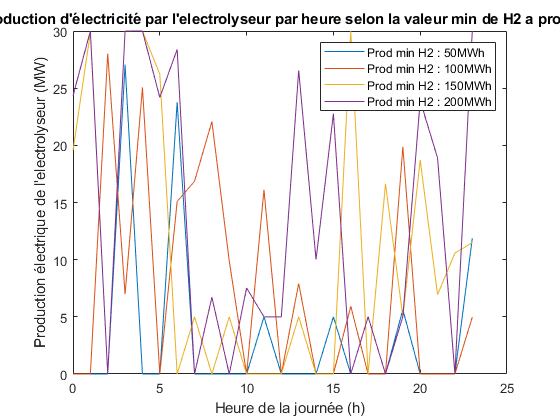

plot(H,mat_sol_ga(1:N,:))
title('Production d''électricité par l''electrolyseur par heure selon la valeur min de H2 a produire ')
xlabel('Heure de la journée (h)')
ylabel('Production électrique de l''electrolyseur (MW)')
legend('Prod min H2 : ' + string(Qjour_H2_ga) + 'MWh')

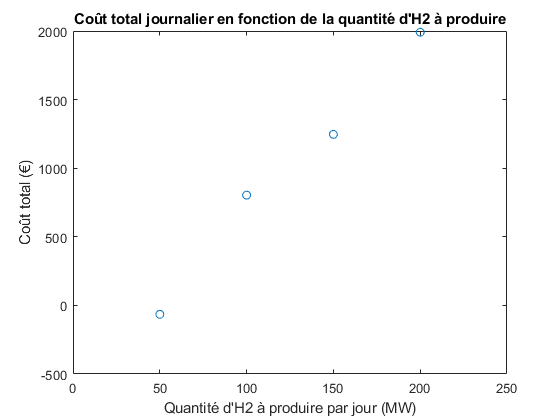


plot(Qjour_H2_ga, mat_fval_ga, 'O')
title("Coût total journalier en fonction de la quantité d'H2 à produire")
xlabel("Quantité d'H2 à produire par jour (MW)")
ylabel("Coût total (€)")
xlim([0 250])

### 6. Solver : particle swarm

% Ajout des contraines sous forme de pénalités
fobj_pso = @(X) fobj(X) + penalite(X, Qjour_H2_pso, etat_elec, N);
swarm_size = [50, 100, 500] ;
s = length(swarm_size);

mat_sol_pso = zeros(2*N,s) ; 
mat_fval_pso = zeros(1,s) ; 

for j = 1:s
    options_pso= optimoptions('particleswarm',"SwarmSize",swarm_size(j)) ; 
    [sol_pso,fval_pso,exitflag_pso,output_pso] = particleswarm(fobj_pso,2*N,lb,ub,options_pso) ;
    mat_sol_pso(:,j) = sol_pso ; 
    mat_fval_pso(:,j) = fval_pso ; 
end

Optimization ended: relative change in the objective value 
over the last OPTIONS.MaxStallIterations iterations is less than OPTIONS.FunctionTolerance.
Optimization ended: relative change in the objective value 
over the last OPTIONS.MaxStallIterations iterations is less than OPTIONS.FunctionTolerance.
Optimization ended: relative change in the objective value 
over the last OPTIONS.MaxStallIterations iterations is less than OPTIONS.FunctionTolerance.


### 7. Résultats avec le solver pso 

disp('Les puissances optimales fournies à chaque heure à l électrolyseur pour chaque taille de population initiale (en MW)')

Les puissances optimales fournies à chaque heure à l électrolyseur pour chaque taille de population initiale (en MW)


disp(mat_sol_pso(1:N,:))

   30.0000   30.0000   30.0000
         0   11.5922   30.0000
   29.3044   19.3110   30.0000
   30.0000   30.0000    1.8073
   30.0000   30.0000    0.1087
   30.0000   30.0000   26.6560
   28.5081   30.0000    6.8606
   30.0000    7.4968         0
    2.8723    0.0000         0
    8.9705   23.7845         0
   24.6415   29.9960         0
         0         0    2.5792
         0         0         0
    0.3710         0         0
         0    0.0062    4.7477
         0   23.8590    1.7062
    7.8673         0   30.0000
   30.0000         0         0
         0    0.0003   23.1147
   29.6287   16.6599   30.0000
   30.0000    4.8234         0
   30.0000   29.9019    1.3481
   30.0000   30.0000   28.7488
    4.6940   30.0000   21.2988



disp('Les coûts journaliers optimaux pour chaque taille de population initiale (en €)')

Les coûts journaliers optimaux pour chaque taille de population initiale (en €)


disp(mat_fval_pso)

  582.9791  426.3727  621.2342



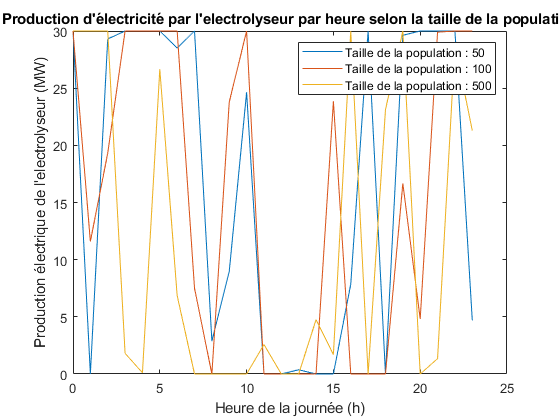

plot(H,mat_sol_pso(1:N,:))
title('Production d''électricité par l''electrolyseur par heure selon la taille de la population')
xlabel('Heure de la journée (h)')
ylabel('Production électrique de l''electrolyseur (MW)')
legend('Taille de la population : ' + string(swarm_size))

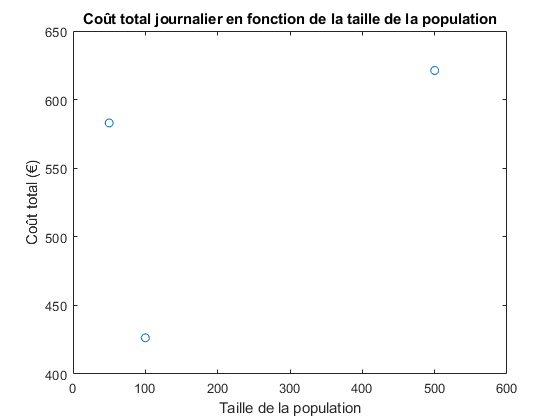


plot(swarm_size, mat_fval_pso, 'O')
title("Coût total journalier en fonction de la taille de la population")
xlabel("Taille de la population")
ylabel("Coût total (€)")
xlim([0 600])

### Fonction pénalité du solver particle swarm 

Cette fonction permet de traduire les contraintes Σ𝜂𝑒𝑙𝑒𝑐𝑃𝑒𝑙𝑒𝑐 ≥ 𝑄𝐻2𝑗𝑜𝑢r et teta est un entier. 

function [c] = penalite(X, Qjour_H2, etat, N)
%on choisit q=2 arbitrairement 
q=2 ; 

%Pénalité traduisant la contrainte Σ𝜂𝑒𝑙𝑒𝑐𝑃𝑒𝑙𝑒𝑐 ≥ 𝑄𝐻2𝑗𝑜𝑢r
c = max(0, Qjour_H2 - etat*X(1:N)*X(N+1:2*N)')^q;

%Nous avons imposé dans les bornes du problème que : 0<teta<1. 
%Pour s'assurer que teta soit un entier, on impose qu'il vale soit 0 soit 1. 
%Pénalité si les teta ne valent pas 0 ou 1 : 
c2 = X(N+1:2*N)*(X(N+1:2*N)'-1); %c2 ne vaut 0 que si les teta valent O ou 1 

c = c + abs(c2)*1e10 ; 

%abs(c2) a une valeur entre 0 et 1. Plus il est proche de 1 (c'est à dire que les teta 
% ne valent pas 0 ou 1)
%plus la pénalité sera grande, et à l'inverse plus il est proche de 0 plus on se rapproche d'une 
% pénalité nulle 
%--> Si le solveur veut éviter la pénalité, il faut que les teta soient
%égaux à 0 ou 1

end